# Método del lugar de las raíces con MATLAB


$$G(s) = \frac{1}{s^3 + 4s^2+(6+k)s+4+k}$$


**Criterio de estabilidad de Routh**


$$s^3$$
            
$$1$$
                
$$k+6$$



$$s^2$$
            
$$4$$
                
$$k+4$$



$$s^1$$
            
$$\frac{3}{4}k+5$$
          
$$0$$



$$s^0$$
            
$$k+4$$
             
$$0$$


Interpretación:

para $L(3)$: $k\geq-20/3$

para $L(4)$: $k\geq-4$ 

En general $k\geq-4$

**Revisar con Matlab el cálculo del criterio**

syms k
[M, L] = routh_hurwitz([1 4 6+k 4+k]);
simplify(L)

$$ans = \left(\begin{array}{c} 1.0\\ 4.0\\ 0.75\,k+5.0\\ k+4.0 \end{array}\right)$$

**Caso: modelo estable**

k = 0;
Numerador = 1;
Denominador = [1 4 6+k 4+k];
sys = tf(Numerador,Denominador)

sys =
 
            1
  ---------------------
  s^3 + 4 s^2 + 6 s + 4
 
Continuous-time transfer function.



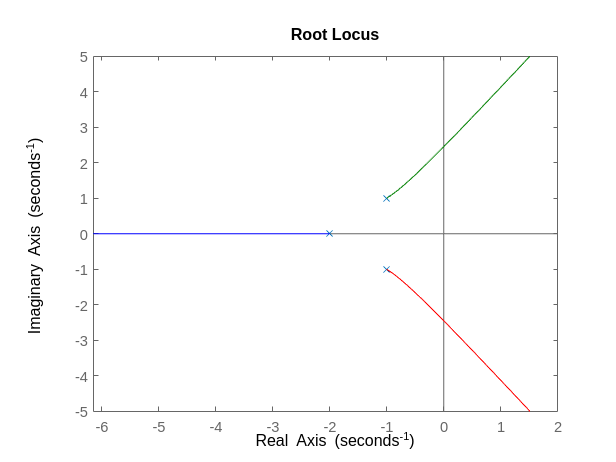

rlocus(sys)

Los polos se encuentran en el semiplano izquierdo, el sistema es estable.

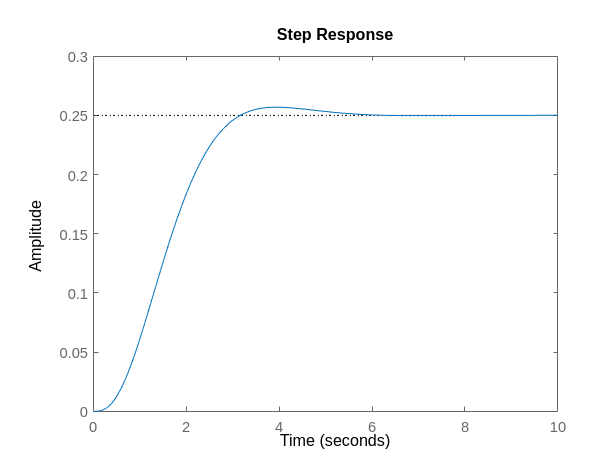

step(sys,0:0.1:10)

**Caso: modelo inestable**

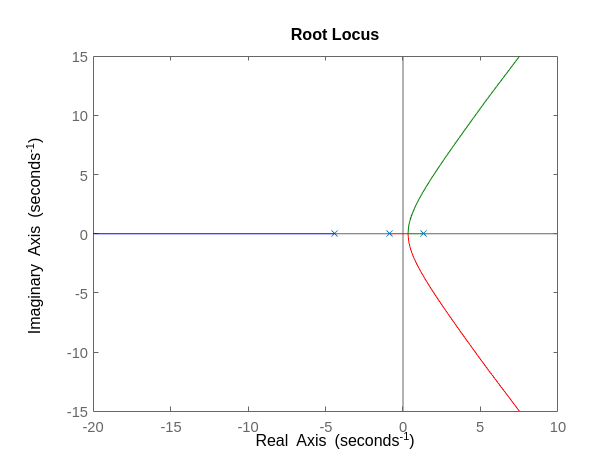

k = -9;
 
Numerador = 1;
Denominador = [1 4 6+k 4+k];
sys = tf(Numerador,Denominador);
rlocus(sys)

Los polos se encuentran en el semiplano derecho, el sistema es inestable.

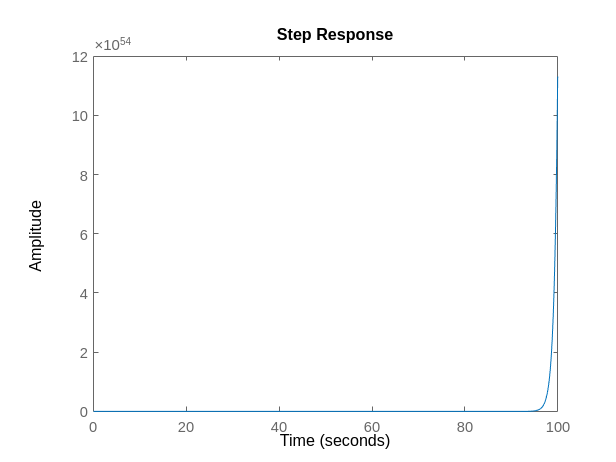

step(sys,0:0.1:100);